# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. Use `pyversion` if you are using a MATLAB version prior to R2019b.

pycheck = pyversion()

pycheck = '3.11'

pyenv()

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\ProgramData\MATLAB\SupportPackages\R2024b\3P.instrset\pythonstandalone_3.11.instrset\win64\python\python.exe"
          Library: "C:\ProgramData\MATLAB\SupportPackages\R2024b\3P.instrset\pythonstandalone_3.11.instrset\win64\python\python311.dll"
             Home: "C:\ProgramData\MATLAB\SupportPackages\R2024b\3P.instrset\pythonstandalone_3.11.instrset\win64\python"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "32180"
      ProcessName: "MATLABPyHost"


เปลี่ยน Python Environment ของ MATLAB

pyenv('Version', 'C:\Users\KantikaWongkasem\AppData\Local\Programs\Python\Python311\python.exe')

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

Import python code from Live Task

% Python code input
pycode2 = [...
"import pandas as pd",...
"# create a two-dimensional list",...
"data = [['John', 25, 'New York'],",...
"       ['Alice', 30, 'London'],",...
"       ['Bob', 35, 'Paris']]",...
"# create a DataFrame from the list",...
"df = pd.DataFrame(data, columns=['Name', 'Age', 'City'])",...
"print(df)",...
""...
];

try
    [data2, df] = pyrun(pycode2, ...
         [ "data" "df" ])
catch ME2
    % Clear temporary variables from workspace and from Python
    clear pycode2;
    rethrow(ME2)
end

    Name  Age      City
0   John   25  New York
1  Alice   30    London
2    Bob   35     Paris


data2 =   Python list with values:

    [['John', 25, 'New York'], ['Alice', 30, 'London'], ['Bob', 35, 'Paris']]

    Use string, double or cell function to convert to a MATLAB array.


df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.int]
     values: [1×1 py.numpy.ndarray]

        Name  Age      City
    0   John   25  New York
    1  Alice   30    London
    2    Bob   35     Paris



% Clear temporary variables from workspace and from Python
clear pycode2;

**เรียกใช้ฟังก์ชันจากไลบรารี Python **`textwrap` โดยเฉพาะ `wrap()` ซึ่งใช้สำหรับ **ตัดข้อความออกเป็นหลายบรรทัด** ตามความกว้างที่กำหนด (`width`)

py.textwrap.wrap("Hello world!", pyargs('width', int8(2)))

ans =   Python list with values:

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

    Use string, double or cell function to convert to a MATLAB array.


แปลงค่าที่ได้จาก Python ให้เป็น cell array หรือ string array ใน MATLAB

cell(py.textwrap.wrap("Hello world!", pyargs('width', int8(2))))

ans = 1×6 cell array
    {1×2 py.str}    {1×2 py.str}    {1×2 py.str}    {1×2 py.str}    {1×2 py.str}    {1×2 py.str}


## Read weather data using Python module 

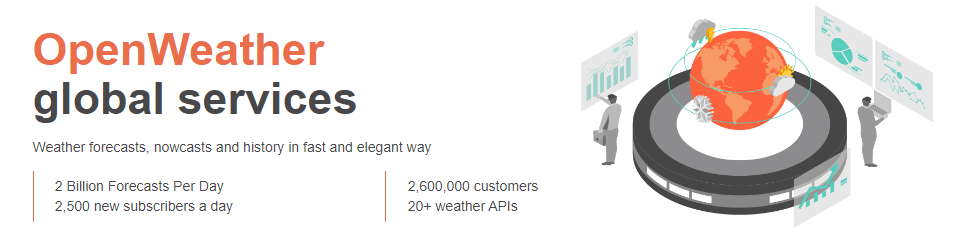

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

## Import Data from Python

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Boston","US",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.0598, 'lat': 42.3584}, 'weather': [{'id': 804, 'main': 'Clouds', 'description': 'overcast clouds', 'icon': '04n'}], 'base': 'stations', 'main': {'temp': 65.21, 'feels_like': 65.43, 'temp_min': 65.21, 'temp_max': 65.21, 'pressure': 1016, 'humidity': 85, 'sea_level': 1016, 'grnd_level': 1012}, 'visibility': 10000, 'wind': {'speed': 13.53, 'deg': 37, 'gust': 22.95}, 'clouds': {'all': 100}, 'dt': 1755499690, 'sys': {'country': 'US', 'sunrise': 1755510897, 'sunset': 1755560486}, 'timezone': -14400, 'id': 4930956, 'name': 'Boston', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 65.21, 'feels_like': 65.43, 'temp_min': 65.21, 'temp_max': 65.21, 'pressure': 1016.0, 'humidity': 85.0, 'sea_level': 1016, 'grnd_level': 1012, 'speed': 13.53, 'deg': 37.0, 'gust': 22.95, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2025-08-18 13:48:36.728857'}


## Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 65.2100
      feels_like: 65.4300
        temp_min: 65.2100
        temp_max: 65.2100
        pressure: 1016
        humidity: 85
       sea_level: [1×1 py.int]
      grnd_level: [1×1 py.int]
           speed: 13.5300
             deg: 37
            gust: 22.9500
             lon: -71.0598
             lat: 42.3584
            city: [1×6 py.str]
    current_time: [1×26 py.str]


Convert the remaining python types to the desired MATLAB data types.

string(data.city)

ans = "Boston"

Perform the remaining conversions using the function below. 

convertData(data)

ans = 1×13 table
      T        P       RH     WindSpd    WindDir    grnd_level    speed    deg    gust      lon       lat        city           DateLocal      
    _____    _____    ____    _______    _______    __________    _____    ___    _____    ______    ______    ________    ____________________

    65.21    65.43    1016      85        1016      1×1 py.int    13.53    37     22.95    -71.06    42.358    "Boston"    18-Aug-2025 13:48:36


## Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Boston!

jsonData = py.weather.get_forecast("Boston","US",apikey.Key);
% forecastData = py.weather.parse_forecast_json(jsonData);
forecastData = py.weather.parse_forecast(jsonData); % returns arrays instead of lists 
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.array.array]
             deg: [1×40 py.array.array]
           speed: [1×40 py.array.array]
        humidity: [1×40 py.array.array]
        pressure: [1×40 py.array.array]


The type of data returned by the parsed forecast date is a **Python array**:

forecast.temp

ans =   Python array:

   64.9200   63.2700   66.6100   69.8200   66.9700   62.0400   58.7100   56.9800   55.2600   60.9100   68.6500   71.3700   70.6100   63.5500   60.5500   60.7300   60.4600   63.3600   71.9100   76.3500   72.5500   67.0500   62.9200   60.8700   59.9200   66.6100   71.8200   72.4500   69.5700   63.8400   62.9100   60.3000   57.1100   61.6300   72.0000   75.2000   74.3000   66.7900   64.3600   63.3000

    Use details function to view the properties of the Python object.

    Use single function to convert to a MATLAB array.


It can be converted to a matrix of doubles:

tempForecast = double(forecast.temp)

tempForecast =    64.9200   63.2700   66.6100   69.8200   66.9700   62.0400   58.7100   56.9800   55.2600   60.9100   68.6500   71.3700   70.6100   63.5500   60.5500   60.7300   60.4600   63.3600   71.9100   76.3500   72.5500   67.0500   62.9200   60.8700   59.9200   66.6100   71.8200   72.4500   69.5700   63.8400   62.9100   60.3000   57.1100   61.6300   72.0000   75.2000   74.3000   66.7900   64.3600   63.3000


Transform **timestamp list** from Python in **MATLAB datetime**:

foreTime = cell(forecast.current_time)

foreTime = 1×40 cell array
    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}


T = cellfun(@string,foreTime)

T = 1×40 string array
    "2025-08-18 09:00:00"    "2025-08-18 12:00:00"    "2025-08-18 15:00:00"    "2025-08-18 18:00:00"    "2025-08-18 21:00:00"    "2025-08-19 00:00:00"    "2025-08-19 03:00:00"    "2025-08-19 06:00:00"    "2025-08-19 09:00:00"    "2025-08-19 12:00:00"    "2025-08-19 15:00:00"    "2025-08-19 18:00:00"    "2025-08-19 21:00:00"    "2025-08-20 00:00:00"    "2025-08-20 03:00:00"    "2025-08-20 06:00:00"    "2025-08-20 09:00:00"    "2025-08-20 12:00:00"    "2025-08-20 15:00:00"    "2025-08-20 18:00:00"    "2025-08-20 21:00:00"    "2025-08-21 00:00:00"    "2025-08-21 03:00:00"    "2025-08-21 06:00:00"    "2025-08-21 09:00:00"    "2025-08-21 12:00:00"    "2025-08-21 15:00:00"    "2025-08-21 18:00:00"    "2025-08-21 21:00:00"    "2025-08-22 00:00:00"    "2025-08-22 03:00:00"    "2025-08-22 06:00:00"    "2025-08-22 09:00:00"    "2025-08-22 12:00:00"    "2025-08-22 15:00:00"    "2025-08-22 18:00:00"    "2025-08-22 21:00:00"    "2025-08-23 00:00:00"    "2025-08-23 03:00:00"   

Convert T in datetime

time = datetime(T)

time = 1×40 datetime array
   18-Aug-2025 09:00:00   18-Aug-2025 12:00:00   18-Aug-2025 15:00:00   18-Aug-2025 18:00:00   18-Aug-2025 21:00:00   19-Aug-2025 00:00:00   19-Aug-2025 03:00:00   19-Aug-2025 06:00:00   19-Aug-2025 09:00:00   19-Aug-2025 12:00:00   19-Aug-2025 15:00:00   19-Aug-2025 18:00:00   19-Aug-2025 21:00:00   20-Aug-2025 00:00:00   20-Aug-2025 03:00:00   20-Aug-2025 06:00:00   20-Aug-2025 09:00:00   20-Aug-2025 12:00:00   20-Aug-2025 15:00:00   20-Aug-2025 18:00:00   20-Aug-2025 21:00:00   21-Aug-2025 00:00:00   21-Aug-2025 03:00:00   21-Aug-2025 06:00:00   21-Aug-2025 09:00:00   21-Aug-2025 12:00:00   21-Aug-2025 15:00:00   21-Aug-2025 18:00:00   21-Aug-2025 21:00:00   22-Aug-2025 00:00:00   22-Aug-2025 03:00:00   22-Aug-2025 06:00:00   22-Aug-2025 09:00:00   22-Aug-2025 12:00:00   22-Aug-2025 15:00:00   22-Aug-2025 18:00:00   22-Aug-2025 21:00:00   23-Aug-2025 00:00:00   23-Aug-2025 03:00:00   23-Aug-2025 06:00:00


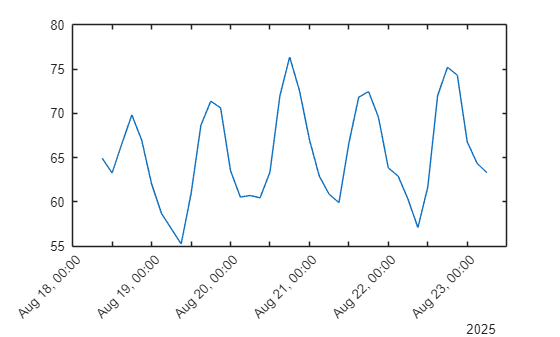

plot(time,tempForecast)
xtickangle(45)

## Preprocess data using MATLAB live task

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

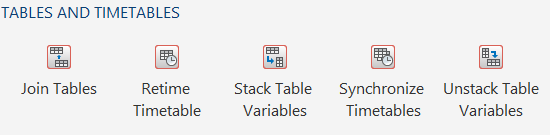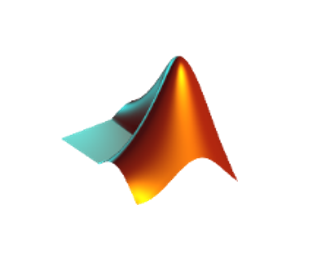

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'})

foreTemp = 40×1 timetable
            Time            Temperature
    ____________________    ___________

    18-Aug-2025 09:00:00       64.92   
    18-Aug-2025 12:00:00       63.27   
    18-Aug-2025 15:00:00       66.61   
    18-Aug-2025 18:00:00       69.82   
    18-Aug-2025 21:00:00       66.97   
    19-Aug-2025 00:00:00       62.04   
    19-Aug-2025 03:00:00       58.71   
    19-Aug-2025 06:00:00       56.98   
    19-Aug-2025 09:00:00       55.26   
    19-Aug-2025 12:00:00       60.91   
    19-Aug-2025 15:00:00       68.65   
    19-Aug-2025 18:00:00       71.37   
    19-Aug-2025 21:00:00       70.61   
    20-Aug-2025 00:00:00       63.55   
    20-Aug-2025 03:

% Retime timetable
Retime = retime(foreTemp,"regular","linear",TimeStep=hours(1))

Retime = 118×1 timetable
            Time            Temperature
    ____________________    ___________

    18-Aug-2025 09:00:00       64.92   
    18-Aug-2025 10:00:00       64.37   
    18-Aug-2025 11:00:00       63.82   
    18-Aug-2025 12:00:00       63.27   
    18-Aug-2025 13:00:00      64.383   
    18-Aug-2025 14:00:00      65.497   
    18-Aug-2025 15:00:00       66.61   
    18-Aug-2025 16:00:00       67.68   
    18-Aug-2025 17:00:00       68.75   
    18-Aug-2025 18:00:00       69.82   
    18-Aug-2025 19:00:00       68.87   
    18-Aug-2025 20:00:00       67.92   
    18-Aug-2025 21:00:00       66.97   
    18-Aug-2025 22:00:00      65.327   
    18-Aug-2025 23:0

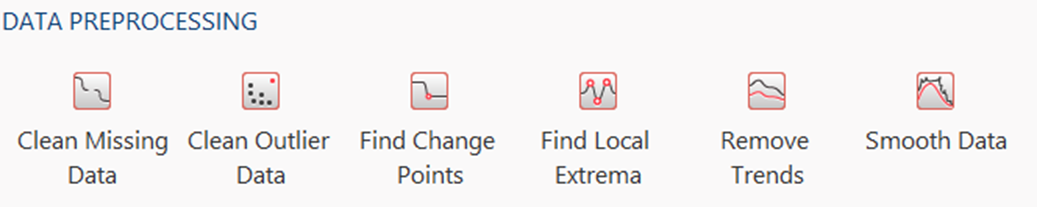

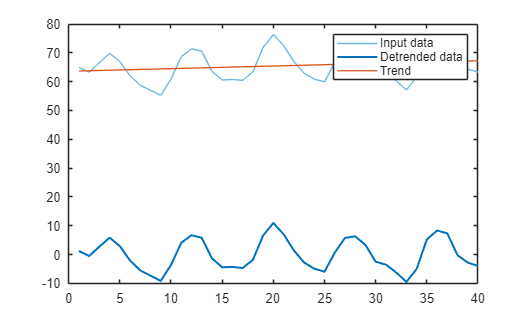

% Remove trend from data
detrendedData = detrend(tempForecast);

% Display results
clf
plot(tempForecast,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(tempForecast-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

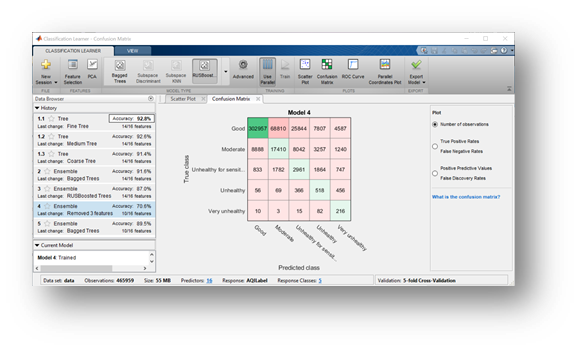

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName        T       P       DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    _____    ____    _____    __    _______    _______    ____    __    __

    18-Aug-2025 13:48:36    "Boston"    Massachusetts    65.21    1016    59.81    85     1012       1016      2025    8     18


Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' is a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel 

airQual = predict(model,currentData)

airQual = categorical
     Moderate 


## Share prediction code

Create a function with these steps to be called in the Python environment.

edit("predictAirQual.m")

See `CallMATLABfromPython.ipynb`

## Reload Python module

Reload *weather.py *after modifications:

%clear classes

%mod = py.importlib.import_module('weather'); 
%py.importlib.reload(mod);

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2015b/matlab/matlab_external/call-modified-python-module.html)

**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end

*Copyright 2018-2021 The MathWorks, Inc.*